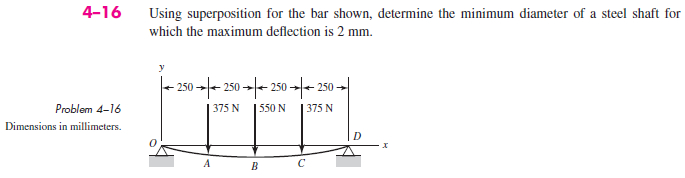

# assumptions

old_assum = assumptions;
clearassum;

# given

u = symunit;
ymax = 2*u.mm;
D = sym('D', 'positive');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ro', 0);
b = b.add('applied', 'force', -375*u.N, 250*u.mm);
b = b.add('applied', 'force', -550*u.N, 500*u.mm);
b = b.add('applied', 'force', -375*u.N, 750*u.mm);
b = b.add('reaction', 'force', 'Rd', 1000*u.mm);
b.L = 1000*u.mm;

# section properties

b.E = 207*u.GPa;
b.I(D) = sympi*(D/2)^4/4;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{8\,x\,\left(8343750\,{\mathrm{mm}}^{2}-13\,x^{2}\right)}{3105\,{\text{D}}^{4}\,\pi }\,{\mathrm{mm}}^{2} & \text{ if }x\leq 250\,\mathrm{mm}\\ \frac{4\,\left(11\,x^{3}+11250\,x^{2}\,\mathrm{mm}-19500000\,x\,{\mathrm{mm}}^{2}+234375000\,{\mathrm{mm}}^{3}\right)}{3105\,{\text{D}}^{4}\,\pi }\,{\mathrm{mm}}^{2} & \text{ if }x\in \left(250\,\mathrm{mm},500\,\mathrm{mm}\right]\\ -\frac{4\,\left(11\,x^{3}-44250\,x^{2}\,\mathrm{mm}+36000000\,x\,{\mathrm{mm}}^{2}-2984375000\,{\mathrm{mm}}^{3}\right)}{3105\,{\text{D}}^{4}\,\pi }\,{\mathrm{mm}}^{2} & \text{ if }x\in \left(500\,\mathrm{mm},750\,\mathrm{mm}\right]\\ -\frac{8\,\left(x-1000\,\mathrm{mm}\right)\,\left(13\,x^{2}-26000\,x\,\mathrm{mm}+4656250\,{\mathrm{mm}}^{2}\right)}{3105\,{\text{D}}^{4}\,\pi }\,{\mathrm{mm}}^{2} & \text{ if }750\,\mathrm{mm}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{8\,\left(2781250\,{\mathrm{mm}}^{2}-13\,x^{2}\right)}{1035\,{\text{D}}^{4}\,\pi }\,{\mathrm{mm}}^{2} & \text{ if }x\leq 250\,\mathrm{mm}\\ \frac{4\,\left(x-500\,\mathrm{mm}\right)\,\left(11\,x+13000\,\mathrm{mm}\right)}{1035\,{\text{D}}^{4}\,\pi }\,{\mathrm{mm}}^{2} & \text{ if }x\in \left(250\,\mathrm{mm},500\,\mathrm{mm}\right]\\ -\frac{4\,\left(x-500\,\mathrm{mm}\right)\,\left(11\,x-24000\,\mathrm{mm}\right)}{1035\,{\text{D}}^{4}\,\pi }\,{\mathrm{mm}}^{2} & \text{ if }x\in \left(500\,\mathrm{mm},750\,\mathrm{mm}\right]\\ -\frac{8\,\left(13\,x^{2}-26000\,x\,\mathrm{mm}+10218750\,{\mathrm{mm}}^{2}\right)}{1035\,{\text{D}}^{4}\,\pi }\,{\mathrm{mm}}^{2} & \text{ if }750\,\mathrm{mm}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 650\,x\,N & \text{ if }x\leq 250\,\mathrm{mm}\\ 25\,\left(11\,x+3750\,\mathrm{mm}\right)\,N & \text{ if }x\in \left(250\,\mathrm{mm},500\,\mathrm{mm}\right]\\ -25\,\left(11\,x-14750\,\mathrm{mm}\right)\,N & \text{ if }x\in \left(500\,\mathrm{mm},750\,\mathrm{mm}\right]\\ -650\,\left(x-1000\,\mathrm{mm}\right)\,N & \text{ if }750\,\mathrm{mm}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 650\,N & \text{ if }x\leq 250\,\mathrm{mm}\\ 275\,N & \text{ if }x\in \left(250\,\mathrm{mm},500\,\mathrm{mm}\right]\\ -275\,N & \text{ if }x\in \left(500\,\mathrm{mm},750\,\mathrm{mm}\right]\\ -650\,N & \text{ if }750\,\mathrm{mm}<x \end{array}\right.$$

w

$$w(x) = 0$$

addvar(y);

# reactions

Ro = r.Ro %#ok

$$Ro = 650\,N$$

Rd = r.Rd %#ok

$$Rd = 650\,N$$

clear Ro Rd;

# shear and moment diagram

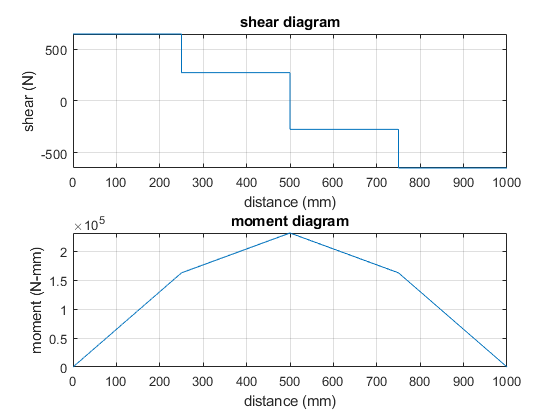

beam.shear_moment(m, v, [0 b.L], {'N' 'mm'});

# maximum deflection

assume(0 <= x & x <= b.L);
xmax = solve(dy == 0, x);
Dmin = simplify(solve(ymax == -y(xmax), D));
Dmin_vpa = vpa(Dmin, 4) %#ok

$$Dmin\_vpa = 32.33\,\mathrm{mm}$$

setassum(old_assum, 'clear');
clear Dmin_vpa old_assum;